# Conjugate Gradient (CG) Method — Individual Project

clc; clear; close all;

## CG Function

function [x, r, r_norm, rel_res, k] = CG_solver(A, b, x0, tol, kmax)
% Solves Ax = b by the Conjugate Gradient method.
% Inputs:  A (SPD matrix), b (rhs), x0 (initial guess), tol, kmax
% Outputs: x (solution), r (residual), r_norm, rel_res, k (iterations)

    x      = x0;
    r      = b - A * x;        % initial residual
    p      = r;                % first search direction = residual
    b_norm = norm(b, 2);
    if b_norm == 0, b_norm = 1; end

    r_norm  = norm(r, 2);
    rel_res = r_norm / b_norm;
    k       = 0;

    while rel_res > tol && k < kmax
        Ap    = A * p;
        rTr   = r' * r;
        alpha = rTr / (p' * Ap);   % optimal step length
        x     = x + alpha * p;
        r_new = r - alpha * Ap;
        beta  = (r_new' * r_new) / rTr;  % direction update scalar
        p     = r_new + beta * p;         % new A-conjugate direction
        r     = r_new;
        k       = k + 1;
        r_norm  = norm(r, 2);
        rel_res = r_norm / b_norm;
    end

    if rel_res <= tol
        fprintf('Converged in %d iterations,  rel. residual = %.2e\n', k, rel_res);
    else
        fprintf('Did not converge in %d iterations,  rel. residual = %.2e\n', k, rel_res);
    end
end

## Test 1 — Small SPD system (n = 5)

n = 5;  rng(42);
R = rand(n);
A = R' * R + n * eye(n)   % SPD by construction

A =     6.9627    1.2180    1.6946    1.0461    0.8661
    1.2180    6.6407    1.0370    0.9667    0.8998
    1.6946    1.0370    6.7123    0.8804    0.5518
    1.0461    0.9667    0.8804    5.6730    0.5990
    0.8661    0.8998    0.5518    0.5990    5.8214


x_exact = rand(n, 1)

x_exact =     0.7852
    0.1997
    0.5142
    0.5924
    0.0465


b = A * x_exact

b =     7.2415
    3.4300
    5.5365
    4.8557
    1.7687


 
% Zero initial guess
[x1, r1, rn1, rr1, k1] = CG_solver(A, b, zeros(n,1), 1e-8, 1000)

Converged in 5 iterations,  rel. residual = 5.40e-17


x1 =     0.7852
    0.1997
    0.5142
    0.5924
    0.0465


r1 = 1.0e-15 *

    0.3398
    0.2777
    0.2990
    0.2044
    0.1766


rn1 = 5.9579e-16

rr1 = 5.4037e-17

k1 = 5

fprintf('||r||_2 = %.4e,  abs. error = %.4e\n', rn1, norm(x1 - x_exact, 2))

||r||_2 = 5.9579e-16,  abs. error = 3.3487e-16


 
% Random initial guess - same solution, possibly different iteration count
[x2, ~, rn2, ~, k2] = CG_solver(A, b, rand(n,1), 1e-8, 1000)

Converged in 5 iterations,  rel. residual = 2.83e-18


x2 =     0.7852
    0.1997
    0.5142
    0.5924
    0.0465


rn2 = 3.1200e-17

k2 = 5

fprintf('Random x0 - abs. error = %.4e\n', norm(x2 - x_exact, 2))

Random x0 - abs. error = 2.2248e-16


## Test 2 — Scaling with system size: n = 100, 1000, 3000

sizes = [100, 1000, 3000];
fprintf('\n  n       Iters   ||r||_2      RelRes       CPU(s)\n')


  n       Iters   ||r||_2      RelRes       CPU(s)


 
for i = 1:length(sizes)
    n = sizes(i);  rng(i);
    R = rand(n);
    A = R' * R + n * eye(n);
    x_exact = rand(n, 1);
    b = A * x_exact;
 
    tic;
    [x_s, ~, rn_s, rr_s, k_s] = CG_solver(A, b, zeros(n,1), 1e-8, 5000);
    t_s = toc;
    fprintf('  %-7d %-7d %-12.4e %-12.4e %.4f\n', n, k_s, rn_s, rr_s, t_s)
end

Converged in 7 iterations,  rel. residual = 4.05e-09


  100     7       5.7229e-05   4.0505e-09   0.0078


Converged in 7 iterations,  rel. residual = 6.29e-09


  1000    7       2.4735e-02   6.2908e-09   0.0027


Converged in 7 iterations,  rel. residual = 1.80e-09


  3000    7       1.1079e-01   1.7995e-09   0.0176


## Test 3 — Sparse matrix: 1D Poisson (FDM, Lecture 8)

n_sp     = 500;
e        = ones(n_sp, 1);
A_sparse = spdiags([-e, 4*e, -e], -1:1, n_sp, n_sp) + speye(n_sp);
x_exact  = ones(n_sp, 1);
b_sp     = A_sparse * x_exact;
 
fprintf('\nSparse test (n=%d, nnz=%d)\n', n_sp, nnz(A_sparse))


Sparse test (n=500, nnz=1498)


tic;
[x_sp, ~, rn_sp, rr_sp, k_sp] = CG_solver(A_sparse, b_sp, zeros(n_sp,1), 1e-8, 10000)

Converged in 11 iterations,  rel. residual = 4.60e-09


x_sp =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


rn_sp = 3.0897e-07

rr_sp = 4.5987e-09

k_sp = 11

t_sp = toc;
fprintf('Iters = %d,  abs. error = %.4e,  CPU = %.4f s\n', ...
    k_sp, norm(x_sp - x_exact, 2), t_sp)

Iters = 11,  abs. error = 7.0426e-08,  CPU = 0.0308 s


## Test 4 — Comparison with MATLAB built-in pcg()

n_c = 300;  rng(7);
R   = rand(n_c);
A_c = R' * R + n_c * eye(n_c);
x_ec = rand(n_c, 1);
b_c  = A_c * x_ec;
 
tic;
[x_our, ~, rn_our, ~, k_our] = CG_solver(A_c, b_c, zeros(n_c,1), 1e-8, 5000)

Converged in 8 iterations,  rel. residual = 1.53e-09


x_our =     0.0193
    0.4554
    0.8874
    0.9332
    0.6220
    0.9134
    0.1859
    0.6027
    0.6168
    0.8594


rn_our = 3.0177e-04

k_our = 8

t_our = toc;
 
tic;
[x_ml, ~, ~, k_ml] = pcg(A_c, b_c, 1e-8, 5000, [], [], zeros(n_c,1))

x_ml =     0.0193
    0.4554
    0.8874
    0.9332
    0.6220
    0.9134
    0.1859
    0.6027
    0.6168
    0.8594


k_ml = 8

t_ml = toc;
rn_ml = norm(b_c - A_c * x_ml, 2)

rn_ml = 3.0177e-04

 
fprintf('\n               Iters   ||r||_2      AbsError     CPU(s)\n')


               Iters   ||r||_2      AbsError     CPU(s)


fprintf('  CG_solver    %-7d %-12.4e %-12.4e %.4f\n', k_our, rn_our, norm(x_our-x_ec,2), t_our)

  CG_solver    8       3.0177e-04   8.5228e-07   0.0122


fprintf('  MATLAB pcg() %-7d %-12.4e %-12.4e %.4f\n', k_ml,  rn_ml,  norm(x_ml -x_ec,2), t_ml)

  MATLAB pcg() 8       3.0177e-04   8.5228e-07   0.0133


## Test 5 — Convergence vs condition number kappa(A)

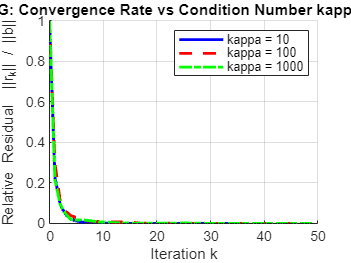


n_cv   = 50;
kappas = [10, 100, 1000];
styles = {'b-', 'r--', 'g-.'};
 
figure; hold on; grid on;
 
for i = 1:length(kappas)
    kap    = kappas(i);
    lam    = linspace(1, kap, n_cv);
    [Q, ~] = qr(randn(n_cv));
    A_cv   = (Q * diag(lam) * Q');
    A_cv   = (A_cv + A_cv') / 2;
 
    b_cv = A_cv * rand(n_cv, 1);
    r_cv = b_cv;
    p_cv = r_cv;
    bn   = norm(b_cv, 2);
    hist = zeros(n_cv+1, 1);
    hist(1) = norm(r_cv,2) / bn;
    x_cv = zeros(n_cv,1);
 
    for ki = 1:n_cv
        Ap       = A_cv * p_cv;
        rTr      = r_cv' * r_cv;
        alpha    = rTr / (p_cv' * Ap);
        x_cv     = x_cv + alpha * p_cv;
        r_new    = r_cv - alpha * Ap;
        beta     = (r_new' * r_new) / rTr;
        p_cv     = r_new + beta * p_cv;
        r_cv     = r_new;
        hist(ki+1) = norm(r_cv,2) / bn;
        if hist(ki+1) < 1e-13, break; end
    end
 
    semilogy(0:ki, hist(1:ki+1), styles{i}, 'LineWidth', 2)
end
 
xlabel('Iteration k')
ylabel('Relative Residual  ||r_k|| / ||b||')
title('CG: Convergence Rate vs Condition Number kappa(A)')
legend('kappa = 10', 'kappa = 100', 'kappa = 1000', 'Location', 'northeast')

 
% Larger kappa slows convergence significantly - motivation for PCG.

%% Test 6 - Matrix Market sparse matrix (gr_30_30)
%  Real sparse SPD matrix loaded from Matrix Market database
%  Size: 900 x 900, nnz = 4380

addpath('C:\Users\gorio\Documents')
A_mm    = mmread('gr_30_30.mtx');
x_exact_mm = ones(900, 1);
b_mm    = A_mm * x_exact_mm;
x0_mm   = zeros(900, 1);

tic;
[x_cg_mm, ~, rn_cg, rr_cg, k_cg] = CG_solver(A_mm, b_mm, x0_mm, 1e-8, 5000);

Converged in 41 iterations,  rel. residual = 7.14e-09


t_cg = toc;
fprintf('CG  Iters=%d, rn=%.4e, err=%.4e, CPU=%.4f\n', ...
    k_cg, rn_cg, norm(x_cg_mm - x_exact_mm, 2), t_cg)

CG  Iters=41, rn=2.3770e-07, err=5.0990e-08, CPU=0.0071



M_mm = ichol(A_mm);

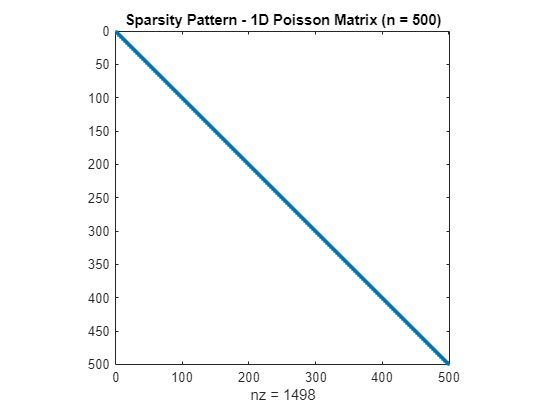

% Sparsity pattern - Poisson matrix
n_sp     = 500;
e        = ones(n_sp, 1);
A_sparse = spdiags([-e, 4*e, -e], -1:1, n_sp, n_sp) + speye(n_sp);

figure;
spy(A_sparse);
title('Sparsity Pattern - 1D Poisson Matrix (n = 500)');
saveas(gcf, 'C:\Users\gorio\Documents\spy_poisson.png')

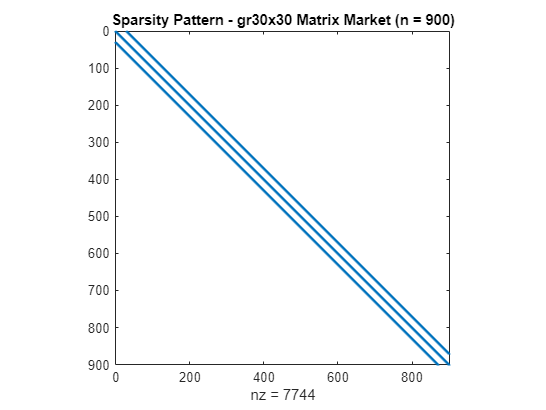


% Sparsity pattern - Matrix Market
A_mm = mmread('gr_30_30.mtx');
figure;
spy(A_mm);
title('Sparsity Pattern - gr30x30 Matrix Market (n = 900)');
saveas(gcf, 'C:\Users\gorio\Documents\spy_gr30.png')

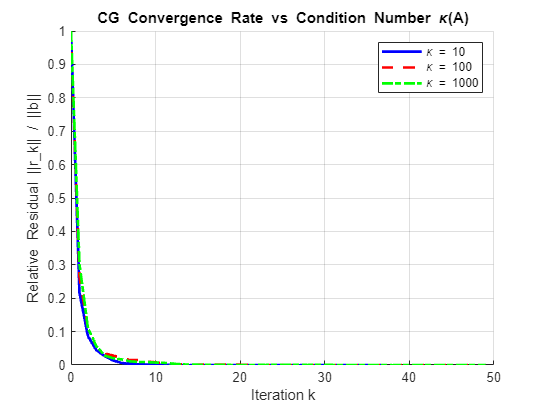


% Convergence plot
n_cv   = 50;
kappas = [10, 100, 1000];
styles = {'b-', 'r--', 'g-.'};
figure; hold on; grid on;

for i = 1:length(kappas)
    kap    = kappas(i);
    lam    = linspace(1, kap, n_cv);
    [Q, ~] = qr(randn(n_cv));
    A_cv   = (Q * diag(lam) * Q');
    A_cv   = (A_cv + A_cv') / 2;
    b_cv   = A_cv * rand(n_cv, 1);
    r_cv   = b_cv;
    p_cv   = r_cv;
    bn     = norm(b_cv, 2);
    hist   = zeros(n_cv+1, 1);
    hist(1) = norm(r_cv,2) / bn;
    x_cv   = zeros(n_cv, 1);

    for ki = 1:n_cv
        Ap       = A_cv * p_cv;
        rTr      = r_cv' * r_cv;
        alpha    = rTr / (p_cv' * Ap);
        x_cv     = x_cv + alpha * p_cv;
        r_new    = r_cv - alpha * Ap;
        beta     = (r_new' * r_new) / rTr;
        p_cv     = r_new + beta * p_cv;
        r_cv     = r_new;
        hist(ki+1) = norm(r_cv,2) / bn;
        if hist(ki+1) < 1e-13, break; end
    end
    semilogy(0:ki, hist(1:ki+1), styles{i}, 'LineWidth', 2)
end

xlabel('Iteration k')
ylabel('Relative Residual ||r\_k|| / ||b||')
title('CG Convergence Rate vs Condition Number \kappa(A)')
legend('\kappa = 10', '\kappa = 100', '\kappa = 1000', 'Location', 'northeast')
saveas(gcf, 'C:\Users\gorio\Documents\convergence_plot.png')